# Representative Signal Chain

## User parameters

% Camera
p.fl    = 0.5;      %[m] focal length
p.dApp  = 0.1;      %[m] Apperture Diameter
p.p     = 5e-6;     %[m] pixel pitch
p.cnt   = 1e3;      %[#] sqrt of number of pixels
p.rate  = [3,50]    %[hz] frame rate of imagery

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
     lPOCA: [0 7000000 0]
      rImg: 30000
    rStart: 840000
      dTgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
       bin: 1


p.int   = [5e-2,1e-3] %[s] integration time

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
     lPOCA: [0 7000000 0]
      rImg: 30000
    rStart: 840000
      dTgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
       bin: 1


p.bgIrr = 1e-6;     %[w/m2/bp] Irradiance on the FP, ideally this would be from a series of simulation 
p.cwl   = 600e-9;   %[m] center wavelength
p.bp    = 400e-9;   %[m] bandpass width
p.bin   = 1;        

% engagement
p.engPhs= 45;   %[deg] Phase angle between sensor and target velocity vectors
p.POCA  = 5e3;  %[m] Seperation of target and sensor at point of closest approach
p.lPOCA = [0,7000e3,0]%[m] Locating Poca location

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
     lPOCA: [0 7000000 0]
      rImg: 30000
    rStart: 840000
      dTgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
       bin: 1


p.rImg  = 30e3; %[s] range which we switch integration 
p.rStart= 840e3;%[m] range from Poca we start the engagement
p.dTgt  = 5;    %[m] Diameter of target
p.rfl   = 1;    %[ratio] reflectance   

% Simulation Params
p.mBuf  = 10;   %[pixels] How much motion we'll allow
p.strOSF= 17;   %[scl] determines how much we'll oversample the psf for the stars
p.tgtOSF= 3;    %[tgt] determines how much we'll over sample the target
p.bgShp = .4;   %[] drives how quickly the SL falls off >1 quicker, <1 slower, 1 = radially
p.maxMag= 13;    %[] drives max mag of those stars (3x drop in stars/mag)

%constants
p.mV_sun = -26.74
p.cLight = 2.99792458e8
p.hPlank = 6.62607015e-34

## Read in data and create LUTs

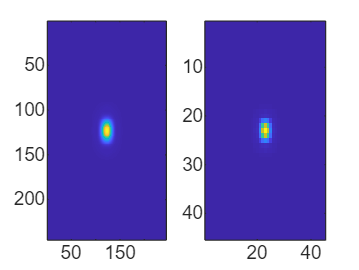

%Make representative SL Im (Ideally this comes from somewhere else, like a
%SL LUT dependant on sun and earth angles + zodiacal)
[x,y]   = meshgrid(linspace(-1,1,p.cnt),linspace(-1,1,p.cnt));
r       = 1-sqrt(x.^2+y.^2); r = r-min(r(:));;
s.bg    = p.bgIrr*abs(r/max(r(:)).^p.bgShp);
if 0; imagesc(abs(r.^p.bgShp)); end; %for testing

% Generate a PRP for our stars (Note: for a system with a changing Focus to
% keep up with the target, this would be an LUT)
[psf, x, y] = diffraction_psf(p.p/p.strOSF, p.fl/p.dApp,p.cwl); % get diffraction psf for CWL
prp0 = conv2(psf,ones(p.strOSF),'same'); %turn it into a prp
s.strPRP = padarray(prp0,[1 1]*round(p.mBuf *p.strOSF/2),0,'both'); %pad array for motion

%Do the same thing for our target. (Note: This should be an LUT based on
%the focus of the system and the range of the target)
[psf, x, y] = diffraction_psf(p.p/p.tgtOSF, p.fl/p.dApp,p.cwl); % get diffraction psf for CWL
prp0 = conv2(psf,ones(p.tgtOSF),'same'); %turn it into a prp
s.tgtPRP = padarray(prp0,[1 1]*round(p.mBuf *p.tgtOSF/2),0,'both'); %pad array for motion
if 1; subplot(1,2,1);imagesc(s.strPRP);subplot(1,2,2);imagesc(s.tgtPRP); end;


%Generate a star LUT
s.starLUT = star_lut(p.maxMag,1); %This will just give a rough

res = 0.0100

samples =    13.0000   12.9900   12.9800   12.9700   12.9600   12.9500   12.9400   12.9300   12.9200   12.9100   12.9000   12.8900   12.8800   12.8700   12.8600   12.8500   12.8400   12.8300   12.8200   12.8100   12.8000   12.7900   12.7800   12.7700   12.7600   12.7500   12.7400   12.7300   12.7200   12.7100   12.7000   12.6900   12.6800   12.6700   12.6600   12.6500   12.6400   12.6300   12.6200   12.6100   12.6000   12.5900   12.5800   12.5700   12.5600   12.5500   12.5400   12.5300   12.5200   12.5100


starLUT =          0         0   12.8751
         0         0   11.5370
         0         0   12.8674
         0         0   12.1393
         0         0   10.2324
         0         0   12.9258
         0         0   12.6831
         0         0   12.2786
         0         0   12.7095
         0         0   12.3770



%get sun irrad
dat = readtable('SolarSpec.txt');

wl = dat.Wavelength_nm_*1e-9;
idx = find((wl>(p.cwl-p.bp/2))==(wl<(p.cwl+p.bp/2)));
s.sun = trapz(dat.Wavelength_nm_(idx),dat.Extraterrestrial_W_m2_nm_(idx)); 

%basic figures of me
s.ifov = p.p/p.fl  %pixel fov

s = struct with fields:
         bg: [1000×1000 double]
     strPRP: [245×245 double]
     tgtPRP: [45×45 double]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
      vSens: [-7000 0 0]
       vTgt: [-4.9497e+03 0 -4.9497e+03]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×761 double)
    tRadDec: [761×2 double]
         tQ: [761×4 double]
      stars: [54×3 double]


s.fov  = s.ifov*p.cnt %system field of view

s = struct with fields:
         bg: [1000×1000 double]
     strPRP: [245×245 double]
     tgtPRP: [45×45 double]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
      vSens: [-7000 0 0]
       vTgt: [-4.9497e+03 0 -4.9497e+03]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×761 double)
    tRadDec: [761×2 double]
         tQ: [761×4 double]
      stars: [54×3 double]


s.cSA  = pi/(4*(p.fl/p.dApp)^2) %Collecting solid angle (gnum/trans)

s = struct with fields:
         bg: [1000×1000 double]
     strPRP: [245×245 double]
     tgtPRP: [45×45 double]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
      vSens: [-7000 0 0]
       vTgt: [-4.9497e+03 0 -4.9497e+03]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×761 double)
    tRadDec: [761×2 double]
         tQ: [761×4 double]
      stars: [54×3 double]



%some place holders
d.sig = zeros(p.cnt/p.bin)

## Generate engagements

% set up relative speeds (assuming everything in space goes 7Km/s)
s.vSens   = [-7e3,0,0]

s = struct with fields:
         bg: [1000×1000 double]
     strPRP: [245×245 double]
     tgtPRP: [45×45 double]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
      vSens: [-7000 0 0]
       vTgt: [-4.9497e+03 0 -4.9497e+03]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×761 double)
    tRadDec: [761×2 double]
         tQ: [761×4 double]
      stars: [54×3 double]


s.vTgt    = [cosd(p.engPhs),0,sind(p.engPhs)]*-7e3

s = struct with fields:
         bg: [1000×1000 double]
     strPRP: [245×245 double]
     tgtPRP: [45×45 double]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
      vSens: [-7000 0 0]
       vTgt: [-4.9497e+03 0 -4.9497e+03]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×761 double)
    tRadDec: [761×2 double]
         tQ: [761×4 double]
      stars: [54×3 double]



%calc engagement range
s.xSens(1,:) = p.lPOCA+[p.rStart, 0, 0];
s.xTgt(1,:)  = p.lPOCA+[cosd(p.engPhs)*p.rStart,-p.POCA,sind(p.engPhs)*p.rStart];
mode = 1

mode = 1

i = 1

i = 1

s.t(1) = 0

s = struct with fields:
         bg: [1000×1000 double]
     strPRP: [245×245 double]
     tgtPRP: [45×45 double]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
      vSens: [-7000 0 0]
       vTgt: [-4.9497e+03 0 -4.9497e+03]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×761 double)
    tRadDec: [761×2 double]
         tQ: [761×4 double]
      stars: [54×3 double]


while mode ~=3
    i = i+1
    s.tMode(i)   = mode;
    s.t(i)       = s.t(i-1)+1/p.rate(mode);    
    s.xSens(i,:) = s.xSens(i-1,:)+s.vSens.*1/p.rate(mode);
    s.xTgt(i,:)  = s.xTgt(i-1,:)+s.vTgt.*1/p.rate(mode);
    if mode == 1 && norm(s.xTgt(i,:)-p.lPOCA)<p.rImg
        mode = mode +1
    elseif mode == 2 && norm(s.xTgt(i,:)-p.lPOCA)>p.rImg
        mode = mode +1
    end
end

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200

i = 201

i = 202

i = 203

i = 204

i = 205

i = 206

i = 207

i = 208

i = 209

i = 210

i = 211

i = 212

i = 213

i = 214

i = 215

i = 216

i = 217

i = 218

i = 219

i = 220

i = 221

i = 222

i = 223

i = 224

i = 225

i = 226

i = 227

i = 228

i = 229

i = 230

i = 231

i = 232

i = 233

i = 234

i = 235

i = 236

i = 237

i = 238

i = 239

i = 240

i = 241

i = 242

i = 243

i = 244

i = 245

i = 246

i = 247

i = 248

i = 249

i = 250

i = 251

i = 252

i = 253

i = 254

i = 255

i = 256

i = 257

i = 258

i = 259

i = 260

i = 261

i = 262

i = 263

i = 264

i = 265

i = 266

i = 267

i = 268

i = 269

i = 270

i = 271

i = 272

i = 273

i = 274

i = 275

i = 276

i = 277

i = 278

i = 279

i = 280

i = 281

i = 282

i = 283

i = 284

i = 285

i = 286

i = 287

i = 288

i = 289

i = 290

i = 291

i = 292

i = 293

i = 294

i = 295

i = 296

i = 297

i = 298

i = 299

i = 300

i = 301

i = 302

i = 303

i = 304

i = 305

i = 306

i = 307

i = 308

i = 309

i = 310

i = 311

i = 312

i = 313

i = 314

i = 315

i = 316

i = 317

i = 318

i = 319

i = 320

i = 321

i = 322

i = 323

i = 324

i = 325

i = 326

i = 327

i = 328

i = 329

i = 330

i = 331

i = 332

i = 333

i = 334

i = 335

i = 336

i = 337

i = 338

i = 339

i = 340

i = 341

i = 342

i = 343

i = 344

i = 345

i = 346

i = 347

i = 348

i = 349

mode = 2

i = 350

i = 351

i = 352

i = 353

i = 354

i = 355

i = 356

i = 357

i = 358

i = 359

i = 360

i = 361

i = 362

i = 363

i = 364

i = 365

i = 366

i = 367

i = 368

i = 369

i = 370

i = 371

i = 372

i = 373

i = 374

i = 375

i = 376

i = 377

i = 378

i = 379

i = 380

i = 381

i = 382

i = 383

i = 384

i = 385

i = 386

i = 387

i = 388

i = 389

i = 390

i = 391

i = 392

i = 393

i = 394

i = 395

i = 396

i = 397

i = 398

i = 399

i = 400

i = 401

i = 402

i = 403

i = 404

i = 405

i = 406

i = 407

i = 408

i = 409

i = 410

i = 411

i = 412

i = 413

i = 414

i = 415

i = 416

i = 417

i = 418

i = 419

i = 420

i = 421

i = 422

i = 423

i = 424

i = 425

i = 426

i = 427

i = 428

i = 429

i = 430

i = 431

i = 432

i = 433

i = 434

i = 435

i = 436

i = 437

i = 438

i = 439

i = 440

i = 441

i = 442

i = 443

i = 444

i = 445

i = 446

i = 447

i = 448

i = 449

i = 450

i = 451

i = 452

i = 453

i = 454

i = 455

i = 456

i = 457

i = 458

i = 459

i = 460

i = 461

i = 462

i = 463

i = 464

i = 465

i = 466

i = 467

i = 468

i = 469

i = 470

i = 471

i = 472

i = 473

i = 474

i = 475

i = 476

i = 477

i = 478

i = 479

i = 480

i = 481

i = 482

i = 483

i = 484

i = 485

i = 486

i = 487

i = 488

i = 489

i = 490

i = 491

i = 492

i = 493

i = 494

i = 495

i = 496

i = 497

i = 498

i = 499

i = 500

i = 501

i = 502

i = 503

i = 504

i = 505

i = 506

i = 507

i = 508

i = 509

i = 510

i = 511

i = 512

i = 513

i = 514

i = 515

i = 516

i = 517

i = 518

i = 519

i = 520

i = 521

i = 522

i = 523

i = 524

i = 525

i = 526

i = 527

i = 528

i = 529

i = 530

i = 531

i = 532

i = 533

i = 534

i = 535

i = 536

i = 537

i = 538

i = 539

i = 540

i = 541

i = 542

i = 543

i = 544

i = 545

i = 546

i = 547

i = 548

i = 549

i = 550

i = 551

i = 552

i = 553

i = 554

i = 555

i = 556

i = 557

i = 558

i = 559

i = 560

i = 561

i = 562

i = 563

i = 564

i = 565

i = 566

i = 567

i = 568

i = 569

i = 570

i = 571

i = 572

i = 573

i = 574

i = 575

i = 576

i = 577

i = 578

i = 579

i = 580

i = 581

i = 582

i = 583

i = 584

i = 585

i = 586

i = 587

i = 588

i = 589

i = 590

i = 591

i = 592

i = 593

i = 594

i = 595

i = 596

i = 597

i = 598

i = 599

i = 600

i = 601

i = 602

i = 603

i = 604

i = 605

i = 606

i = 607

i = 608

i = 609

i = 610

i = 611

i = 612

i = 613

i = 614

i = 615

i = 616

i = 617

i = 618

i = 619

i = 620

i = 621

i = 622

i = 623

i = 624

i = 625

i = 626

i = 627

i = 628

i = 629

i = 630

i = 631

i = 632

i = 633

i = 634

i = 635

i = 636

i = 637

i = 638

i = 639

i = 640

i = 641

i = 642

i = 643

i = 644

i = 645

i = 646

i = 647

i = 648

i = 649

i = 650

i = 651

i = 652

i = 653

i = 654

i = 655

i = 656

i = 657

i = 658

i = 659

i = 660

i = 661

i = 662

i = 663

i = 664

i = 665

i = 666

i = 667

i = 668

i = 669

i = 670

i = 671

i = 672

i = 673

i = 674

i = 675

i = 676

i = 677

i = 678

i = 679

i = 680

i = 681

i = 682

i = 683

i = 684

i = 685

i = 686

i = 687

i = 688

i = 689

i = 690

i = 691

i = 692

i = 693

i = 694

i = 695

i = 696

i = 697

i = 698

i = 699

i = 700

i = 701

i = 702

i = 703

i = 704

i = 705

i = 706

i = 707

i = 708

i = 709

i = 710

i = 711

i = 712

i = 713

i = 714

i = 715

i = 716

i = 717

i = 718

i = 719

i = 720

i = 721

i = 722

i = 723

i = 724

i = 725

i = 726

i = 727

i = 728

i = 729

i = 730

i = 731

i = 732

i = 733

i = 734

i = 735

i = 736

i = 737

i = 738

i = 739

i = 740

i = 741

i = 742

i = 743

i = 744

i = 745

i = 746

i = 747

i = 748

i = 749

i = 750

i = 751

i = 752

i = 753

i = 754

i = 755

i = 756

i = 757

i = 758

i = 759

i = 760

i = 761

mode = 3

    
    
%% Get Pointing
dx  = s.xTgt - s.xSens;
dv  = repmat(s.vTgt - s.vSens,[length(dx),1]);
los = dx(:,1:3) ./ vecnorm(dx(:,1:3),2,2);
omega   = cross(dx(:,1:3),dv,2) ./ dot(dx(:,1:3),dv,2);
omega_poca = omega ./ sqrt(sum(omega.^2, 2));
oz_des  = omega_poca;
oy_des  = cross(oz_des, los, 2); oy_des = oy_des ./ vecnorm(oy_des,2,2);
ox_des  = cross(oy_des, oz_des, 2);
R_desHat= pagetranspose(reshape([ox_des oy_des oz_des]',3,3,[]));
s.tQ      = dcm2quat(R_desHat); %direction cosine matric to quaternions

% Get RaDec for optical axes
opticAx = quatrotate(quatconj(s.tQ),[1,0,0]);
s.tRadDec = [atan2(opticAx(:,2),opticAx(:,1)),...
    asin(opticAx(:,3))/2];
s.tRadDec(:,1) = s.tRadDec(:,1)+pi

s = struct with fields:
         bg: [1000×1000 double]
     strPRP: [245×245 double]
     tgtPRP: [45×45 double]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
      vSens: [-7000 0 0]
       vTgt: [-4.9497e+03 0 -4.9497e+03]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×761 double)
    tRadDec: [761×2 double]
         tQ: [761×4 double]
      stars: [54×3 double]


clearvars -except s p %just keeping our workspace tidy

## Simulate Engagement

% set bounds for which stars we'll keep in analysis
buf = sqrt(sum(s.fov.^2)/2)

buf = 0.0071


t = 1  %for t = 1:length(s.t)

t = 1

 
    raBnd1 = s.tRadDec(t,1)+[-1,1]*buf;
    decBnd = s.tRadDec(t,2)+[-1,1]*buf;
    
    % If RA bounds roll over at all, create another bound which we'll check. 
    if raBnd1(1)<-pi 
        raBnd2=[raBnd1(1)+2*pi,pi];
    elseif raBnd1(2)>pi
        raBnd2=[-pi,raBnd1(2)-2*pi];
    else
        raBnd2=raBnd1;
    end
    
    %%%%%% create library of stars that are near the FOV
    idx = find((((s.starLUT(:,1)>raBnd1(1)) & (s.starLUT(:,1)<raBnd1(2))) |...
        ((s.starLUT(:,1)>raBnd2(1)) & (s.starLUT(:,1)<raBnd2(2)))) &...
        ((s.starLUT(:,2)>decBnd(1)) & (s.starLUT(:,2)<decBnd(2))));
    s.stars = s.starLUT(idx,:);

    % Create unit vector for stars so that we can rotate this vector
    % from reported J2000 GCRS frame to the instantaneous MOD frame
    starV = [cos(s.stars(:,1)).*cos(s.stars(:,2)) ...
        sin(s.stars(:,1)).*cos(s.stars(:,2)) ...
         sin(s.stars(:,2))];


    %%%%%%% rotate stars to optical frame and turn into pixel coords
    starP = quatrotate(s.tQ(1,:), starV);
    x = starP(:,2)./starP(:,1); % [rad,p] Yp becomes FP_X "left"
    y = starP(:,3)./starP(:,1); % [rad,p] Zp becomes FP_Y "up"
    %get in units of FOVs, then scale to pixels
    px = (-y/s.fov+0.5)*p.cnt/p.bin-0.5;
    py = (-x/s.fov+0.5)*p.cnt/p.bin-0.5;

%%%%%%% get motion vector by looking at raDec pointing
    % frame and this frame. 
    di = 0; % These become a vector of points to sample the motion. 
    dj = 0;
    if (p.mBuf>1) & t>1                
        % get the RaDec looking point
        pt =   [cos(s.tRadDec(t,1)).*cos(s.tRadDec(t,2)) ...
                sin(s.tRadDec(t,1)).*cos(s.tRadDec(t,2)) ...
                 sin(s.tRadDec(t,2))];         
        %rotate current looking point by last quaternion             
        starP0 = quatrotate(s.tQ(t-1,:), pt); % look at our current quat rotated to our center point
        x0 = starP0(:,2)./starP0(:,1); % [rad] Yp becomes FP_X "left"
        y0 = starP0(:,3)./starP0(:,1); % [rad] Zp becomes FP_Y "up"
        %get in units of FOVs, then scale to pixels
        px0 = (-y0/s.fov+0.5)*p.cnt/s.bin-0.5;
        py0 = (-x0/s.fov+0.5)*p.cnt/s.bin-0.5;
        
        % get difference in location in pixels 
        if p.frame == 1
            dt = s.t(t)-s.t(t-1)
        end
        dx = (p.cnt/2 - px0)*dt;
        dy = (p.cnt/2 - py0)*dt;
        di = round(p.prpOSF*p.bin*linspace(-dx/2,dx/2,p.mBuf));
        dj = round(p.prpOSF*p.bin*linspace(-dy/2,dy/2,p.mBuf));
        blur = sum([dx,dy].^2)^.5;

    end            
% get only the stars contained within FOV. 
f = (px > 0) & (py > 0) & (px<(p.cnt/p.bin)) & (py<(p.cnt/p.bin));

Index exceeds the number of array elements. Index must not exceed 1.

px = px(f);
py = py(f);

% turn into irradiance and then electrons
irrApp = s.sun*10.^(-(stars(f,3)-p.mV_sun)/2.5);
elec   = irrApp.*p.cwl/p.hPlank/p.cLight*p.int.*pi*(p.dApp^2-p.dObs^2)/4; 
% get pixel locations    
I = round(px);
J = round(py);
% and phasing for PRP
i = round(p.prpOSF*(px-I));
j = round(p.prpOSF*(py-J));

%end



## Functions

% Generate a psf
function [psf, x, y] = diffraction_psf(pixel_pitch, f_number, wavelength)
    % Generates the diffraction-limited point spread function (PSF).
    
    % Input arguments:
    %   pixel_pitch: Pixel pitch in meters.
    %   f_number: f-number of the optical system.
    %   wavelength (optional): Wavelength of light in meters. Defaults to 550nm.
    
    % Output arguments:
    %   psf: The PSF array.
    %   x: The x-coordinates of the PSF grid.
    %   y: The y-coordinates of the PSF grid.
    
    if nargin < 3
        wavelength = 550e-9; % Default wavelength: green light
    end
    
    % Calculate the Airy disk radius (first minimum)
    airy_radius = 1.22 * wavelength * f_number;
    
    % Create a grid for the PSF
    psf_size = ceil(6 * airy_radius / pixel_pitch); % Size of the PSF array
    if mod(psf_size, 2) == 0  % Ensure psf_size is odd for centering
        psf_size = psf_size + 1;
    end
    
    x = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    y = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    [X, Y] = meshgrid(x, y);
    r = sqrt(X.^2 + Y.^2);
    
    % Calculate the PSF using the Airy disk formula
    psf = zeros(size(r));
    nonzero_r = r > 0;
    psf(nonzero_r) = (2 * besselj(1, pi * r(nonzero_r) / airy_radius) ./ (pi * r(nonzero_r) / airy_radius)).^2;
    psf(r == 0) = 1.0; % Central maximum
    
    % Normalize the PSF (integral should be 1)
    psf = psf / sum(psf(:));
end

function starLUT = star_lut(mag,scl)
% This will just generate a random distribution of stars. For magnitudes,
% it uses the rough approximation that every order of magnitude yields a
% factor of 3 increase in the number of stars to create a PDF. Also note,
% we add additional stars that go beyond the circle coordinate system (<-pi
% to >pi) for the ease of sampling the stars when our FoV is on the edge of
% the right assention. Probably a nicer way to handle this. 

% Input arguments:
%   mag: limits the maximum magnitude of stars
%   count: number of stars in total

% Output arguments:
%   a mock star catalog

%set up sampling
res     = 0.01
samples = mag-[0:res:mag]
%create a pdf using the approximation that every magnitude there are about
%3x as many stars
magPDF = 3.^((mag-[0:.01:mag]));
num_samples = round(sum(magPDF*res)*scl*1.1);

%get number or magnitude quantizations
n_categories = length(magPDF);

% Create the cumulative distribution function (CDF).
cdf = cumsum(magPDF)/sum(magPDF);

% Generate uniform random numbers between 0 and 1.
random_numbers = rand(num_samples, 1);

% Initialize the output vector.
starLUT = zeros(num_samples, 3);

% Use CDF to distribute magnitudes appropriately
for i = 1:n_categories
  starLUT((random_numbers <= cdf(i)) == (starLUT(:,3)==0),3) = samples(i);  
end
starLUT(:,3) = starLUT(:,3) + (rand(num_samples, 1)-0.5).*res % this make the quantization less obvious
starLUT(:,1) = (rand(num_samples,1)-.5)*(pi*1.1);
starLUT(:,2) = (rand(num_samples,1)-.5)*(pi/2);

end